# Documentation

This is an illustration of the generation of a non-gaussian random process based on a gaussian one. This method applies well for low skewness, and high kurtosis.

## Initialisation

clearvars;close all;clc

% Set the input
N = 1e6; % number of data points
m1 = 10; % mean  of x
m2 = 4; % variance of x
x = m1+sqrt(m2).*randn(1,N); % random gaussian vector of mean m1 and variance m2

% Target:
m3 = 1; % target skewness. NB: m3 is equal to 0 for a gaussian variable
m4 = 6 ; % target kurtosis. NB: m4 is equal to 3 for a gaussian variable

## Transformation into a non-Gaussian distribution

% compute the new random variable y that is non-gaussian.
[y] = MBHTM(x,m3,m4);

applicability condition is verified 
13.1 >= m3^2 = 1 

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


##  Verification

% Gaussianity fit for x
figure
histogram(x,'binwidth',0.1,Normalization="pdf",EdgeColor="none")
hold on
histogram(y,'binwidth',0.1,Normalization="pdf",EdgeColor="none")
set(gcf,'units','normalized','outerposition', [0.1 0.1 0.8 0.8])
set(gcf,'color','w')
xlabel(' x ');
ylabel('normalized pdf');
leg1 = ['m_1 = ',num2str(mean(x),2),...
    ', m_2 = ',num2str(var(x),2),...
    ', m_3 = ',num2str(skewness(x),2),...
    ', m_4 = ',num2str(kurtosis(x),2)];
leg2 = ['m_1 = ',num2str(mean(y),2),...
    ', m_2 = ',num2str(var(y),2),...
    ', m_3 = ',num2str(skewness(y),2),...
    ', m_4 = ',num2str(kurtosis(y),2)]

leg2 = 'm_1 = 10, m_2 = 4, m_3 = 1, m_4 = 6'

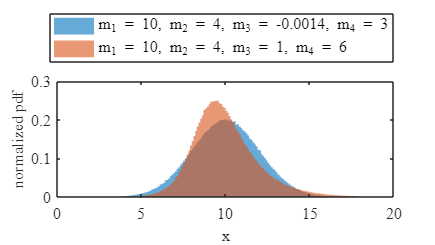

legend(leg1,leg2,'Location','northoutside');
xlim([0,20])
set(findall(gcf,'-property','fontSize'),'fontsize',12,'fontname','Times')